# ECE 6530: Final Project

*M. Adkins, F. Mino, F. Ordubadi, and V. Rao (2023)*

## Data Acquisition

This data is meant to simulate Peripheral Nervous System (PNS) neural data collected as described in Fig. 3.1-2 of [Warren et. al 2016](https://doi-org.ezproxy.lib.utah.edu/10.1109/JPROC.2015.2507180).

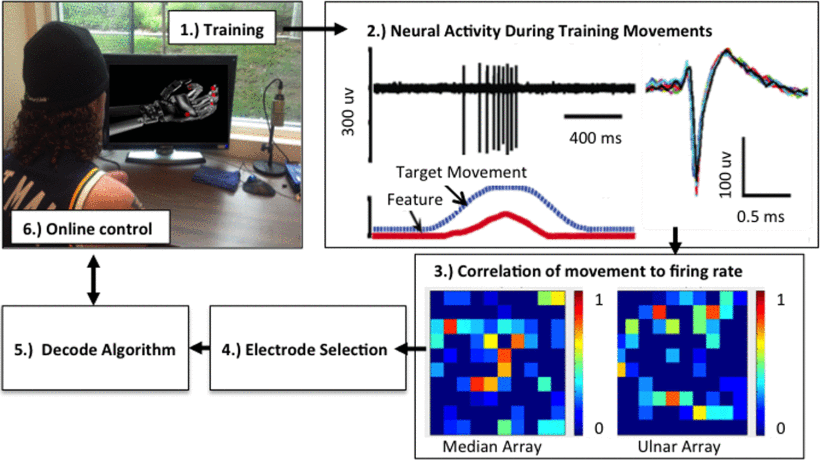

## Load Data

This is simulated data provided for the Introduction to NeuroRobotics course by Jacob George, PhD.

load("./data/project_data.mat")

## Visualize Data

### Neural Data

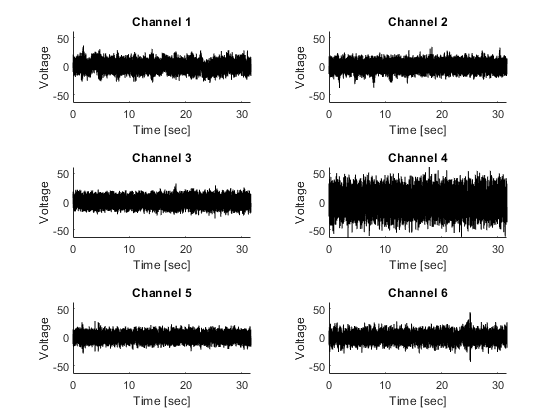

fs = 30e3; % sampling frequency
t = (1:length(unfilteredNeuralData))'/fs;
tlo = tiledlayout('flow');
ax = [];%
for channel = 1:6
    ax(channel) = nexttile; plot(t, unfilteredNeuralData(:,channel), 'k')
    ylabel("Voltage")
    xlabel("Time [sec]")
    title(sprintf("Channel %d", channel))
    box off
end
linkaxes(ax, 'y')

### Target Movements (a.k.a. Kinematics)

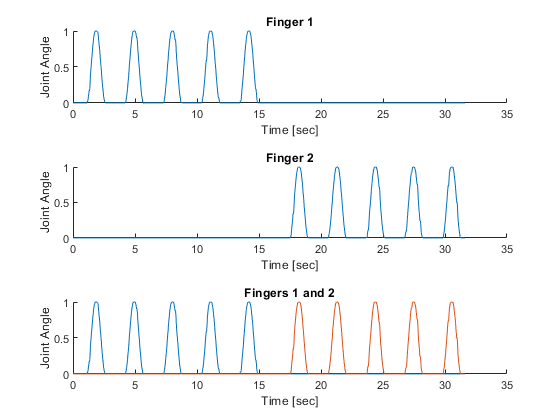

tlo = tiledlayout(3,1);
for finger=1:2
    nexttile; plot(t, Kinematics(:,finger))
    ylabel("Joint Angle")
    xlabel("Time [sec]")
    title(sprintf("Finger %d", finger))
    box off
end
nexttile; plot(t, Kinematics)
ylabel("Joint Angle")
xlabel("Time [sec]")
title("Fingers 1 and 2")
box off

### Combined Visualization

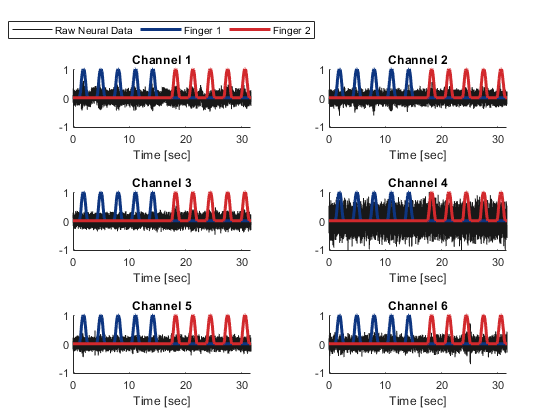

tlo = tiledlayout('flow');

my_palette = [24,24,24; 13,53,128; 210,41,45]/(255);
set(tlo,'DefaultAxesColorOrder', my_palette)
ax = [];

raw_data_norm = unfilteredNeuralData/max(unfilteredNeuralData(:));
for channel = 1:6
    ax(channel) = nexttile;
    plot(t, raw_data_norm(:,channel));
    hold on
    plot(t, Kinematics, LineWidth=2.25)
    hold off
    box off
    title(sprintf("Channel %d", channel))
    xlabel("Time [sec]")
    if channel==1
        legend({"Raw Neural Data", "Finger 1", "Finger 2"}, Location = 'northoutside', Orientation='horizontal')
    end
end
linkaxes(ax, 'y')

## Project Description

It is known that neural data is **nonlinear, nonstationary, and noisy**. [[Wu et al. 2008](https://doi.org/10.1109%2FTNSRE.2008.922679)]

The NeuroRobotics Lab at the University of Utah has attempted to decode Kinematic data from Neural data by using time-domain features, notably, MAV and spike rates. [[Page et al. 2018](https://doi.org/10.3389/fnhum.2018.00352)]

In this project, we will explote time-frequency features for a regression algorithm such as a Kalman Filter or a Neural Network.

We have selected three methods based on Table 1. of [Huang et al. 2008](https://doi.org/10.1029/2007RG000228)

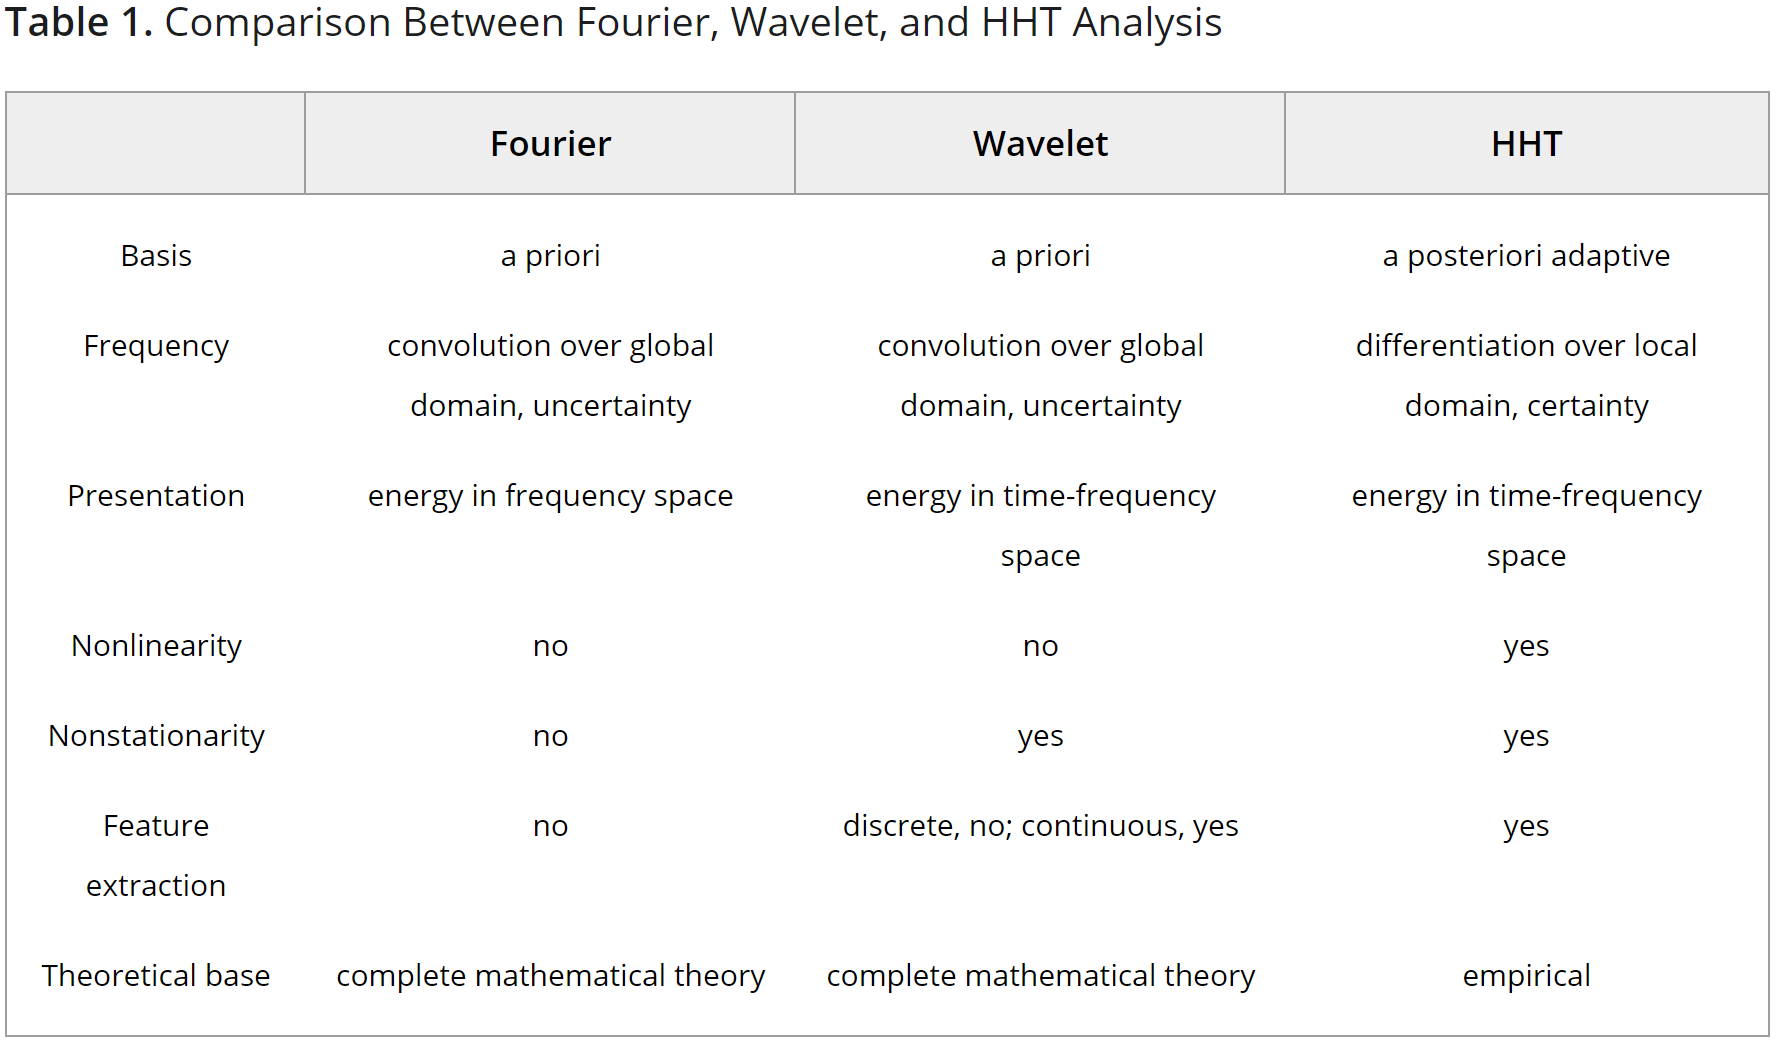

All three of these methods will output a time-frequency image (2D) signal for each channel. These new signals can then be fed to the regressors, and decoding performance should serve as a comparison metric for each of the methods.

#### STFT

[MATLAB STFT Tutorial](https://www.mathworks.com/help/signal/ref/stft.html)

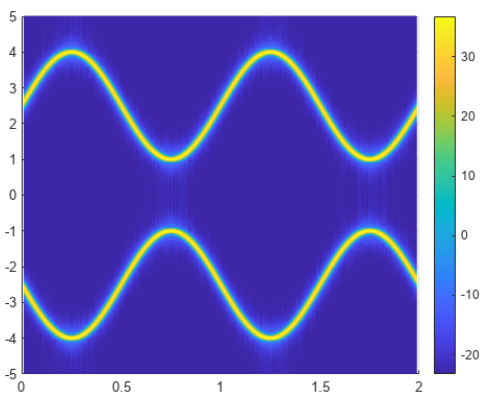

#### Wavelet Transform (Discrete & Continuous)

[MATLAB Wavelet Analysis of Frequency Bank Tutorial](https://www.mathworks.com/help/wavelet/ug/continuous-and-discrete-wavelet-analysis.html)

#### 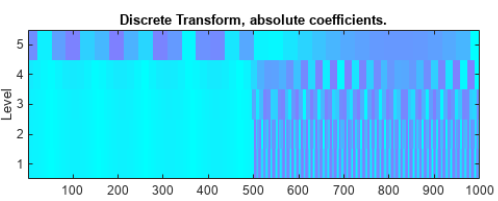

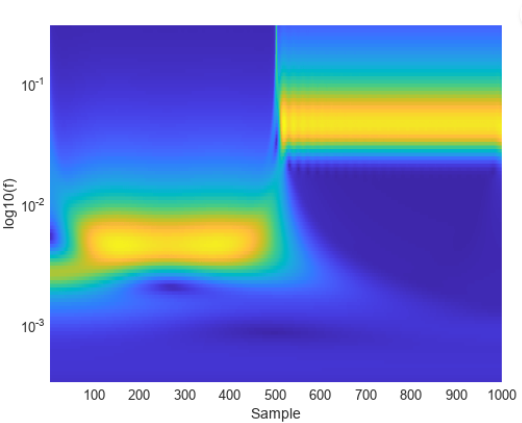

#### Hilbert-Huang Transform

[MATLAB HHT Tutorial](https://www.mathworks.com/help/signal/ref/hht.html)

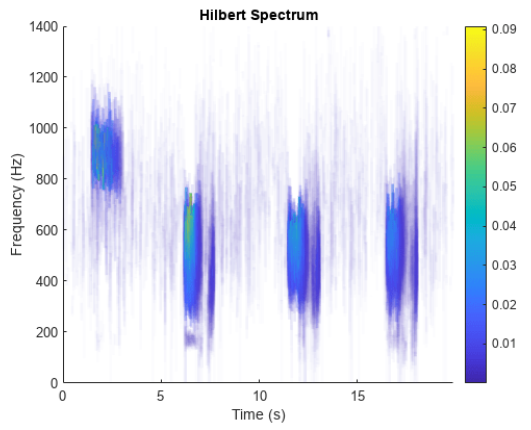

#### Example of Desired Ouput Plot

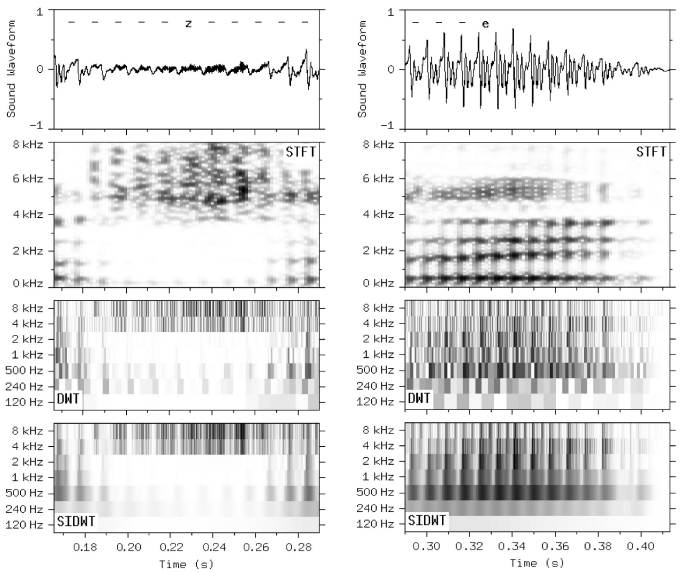

## STFT

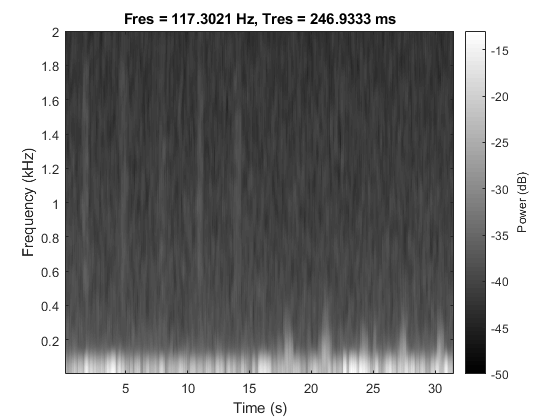

signal = raw_data_norm(:,1);
tlo = tiledlayout('flow');
pspectrum(signal,fs,'spectrogram','Leakage',0.2,'OverlapPercent',80,'FrequencyLimits',[1 2000],'MinThreshold',-50)
colormap(gray(80))

## DWT

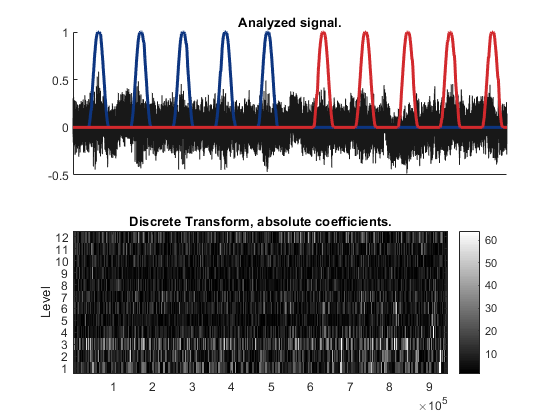

lev   = 12;
wname = 'fk4';
nbcol = 64;
[c,l] = wavedec(signal,lev,wname);


len = length(signal);
cfd = zeros(lev,len);
for k = 1:lev
    d = detcoef(c,l,k);
    d = d(:)';
    d = d(ones(1,2^k),:);
    cfd(k,:) = wkeep(d(:)',len);
end
cfd =  cfd(:);
I = find(abs(cfd)<sqrt(eps));
cfd(I) = zeros(size(I));
cfd    = reshape(cfd,lev,len);
cfd = wcodemat(cfd,nbcol,'row');

figure
h211 = subplot(2,1,1);
h211.XTick = [];
set(gca,'ColorOrder', my_palette, 'NextPlot', 'replacechildren');
plot(signal);
hold on
plot(Kinematics, LineWidth=2.25)
hold off
title('Analyzed signal.');
ax = gca;
ax.XLim = [1 length(signal)];
subplot(2,1,2);
colormap(gray(80));
imagesc(flip(cfd));

colorbar
tics = 1:lev;
labs = int2str(tics');
ax = gca;
ax.YTickLabelMode = 'manual';
ax.YDir = 'normal';
ax.Box = 'On';
ax.YTick = tics;
ax.YTickLabel = labs;
title('Discrete Transform, absolute coefficients.');
ylabel('Level');

## CWT

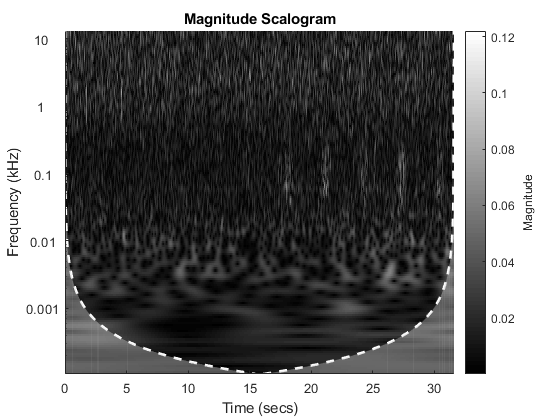

cwt(signal, fs)

## HHT

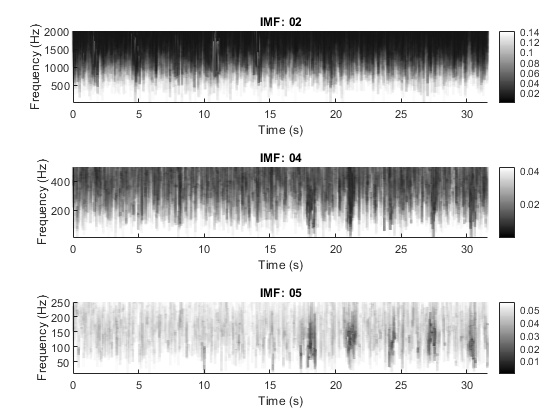

n_imf = 7;
imf = emd(signal,'MaxNumIMF',n_imf,'Display',0);

tlo = tiledlayout(3,1);
ax = [];
for i = [2,4,5]
    ax(i) = nexttile;
    hht(imf(:,i),fs,FrequencyLimits=[10 8000/(2^i)])
    title(sprintf("IMF: %02d", i))
end
colormap(ax(2), gray(80));
colormap(ax(4), gray(80));
colormap(ax(5), gray(80));

## Presentation Figures

For this section we provide the code used to generate the figures used in the presentation, and the members that worked on them.

These being

Short Time Fourier Transform (STFT) - Michael Adkins

Discrete Wavelet Transform (DWT) - Fredi Mino

Continous Wavelet Transform (CWT) - Farzad

Hilbert-Huang Transform (HHT) - Vaishnavi Rao

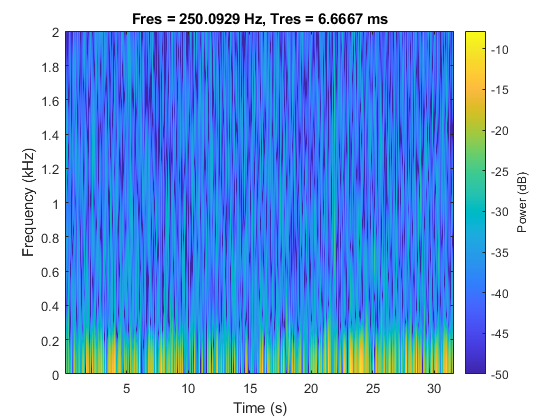

% STFT
figure()
pspectrum(signal,fs,'spectrogram','FrequencyLimits',[1 2000],'Leakage',0.80,'MinThreshold',-50, 'OverlapPercent',80, 'FrequencyResolution',250)

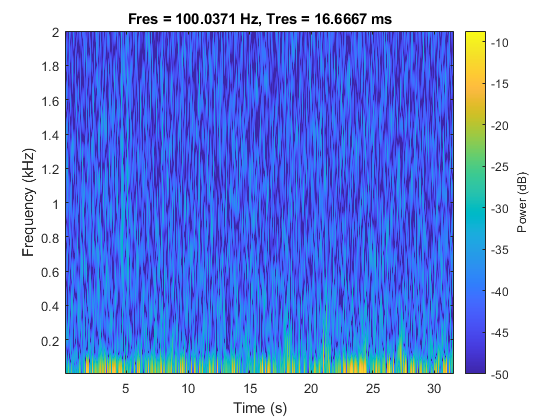

pspectrum(signal,fs,'spectrogram','FrequencyLimits',[1 2000],'Leakage',0.80,'MinThreshold',-50, 'OverlapPercent',80, 'FrequencyResolution',100)

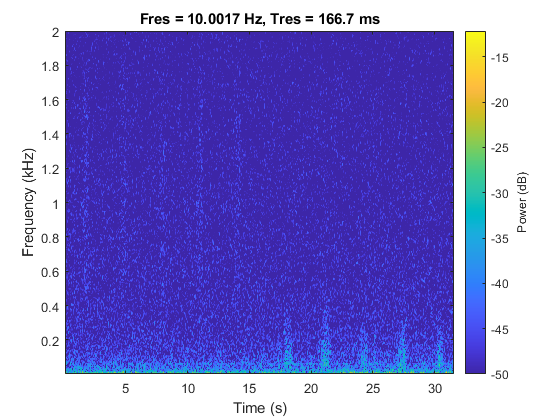

pspectrum(signal,fs,'spectrogram','FrequencyLimits',[1 2000],'Leakage',0.80,'MinThreshold',-50, 'OverlapPercent',80, 'FrequencyResolution',10)

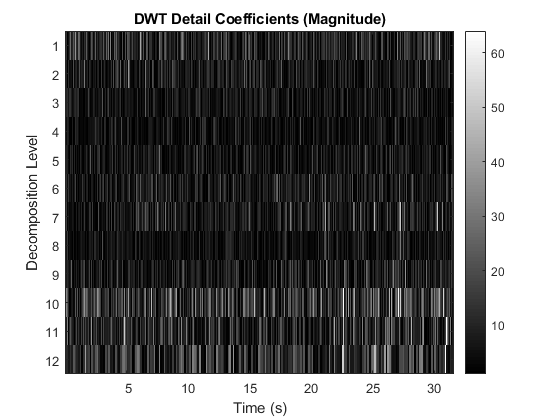


% DWT

fig = figure();
% fontsize(fig, 18, "points")
colormap(gray(100));
imagesc(flip(cfd));
x_tic_labels = 0:5:30;
x_tics = x_tic_labels*fs;

colorbar
tics = 1:lev;
tic_labels = lev:-1:1;
labs = int2str(tic_labels');
ax = gca;
ax.YTickLabelMode = 'manual';
ax.YDir = 'normal';
ax.Box = 'On';
ax.YTick = tics;
ax.YTickLabel = labs;

ax.XTick = x_tics;
ax.XTickLabel = int2str(x_tic_labels');
title('DWT Detail Coefficients (Magnitude)');
ylabel('Decomposition Level');
xlabel("Time (s)")

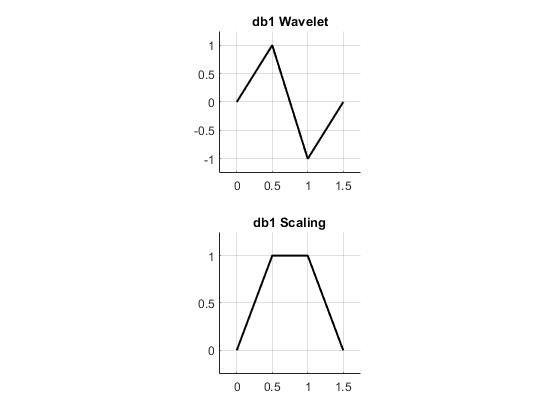

wname = 'db1';
itr = 100;
[phi,psi,xval] = wavefun(wname,1);
tlo = tiledlayout(2,1);

nexttile; plot(xval,psi, 'k-', LineWidth=1.5)
grid on; axis square; box off
title([wname,' Wavelet'])
plot_offset = 0.25; 
xlim([min(xval)-plot_offset, max(xval)+plot_offset])
ylim([min(psi)-plot_offset, max(psi)+plot_offset])

nexttile; plot(xval,phi, 'k-', LineWidth=1.5)
grid on; axis square; box off
title([wname,' Scaling'])
xlim([min(xval)-plot_offset, max(xval)+plot_offset])
ylim([min(phi)-plot_offset, max(phi)+plot_offset])

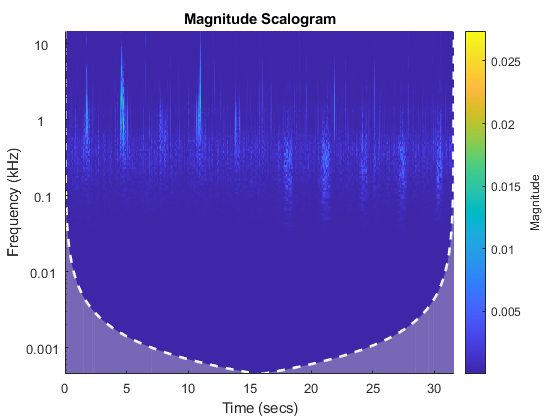

% CWT

%% Denoise Neural Data
filtered_neural_data = [];
quiescent_period = 15.5*fs:17*fs;

for ch_idx=1:6
    denoised_ch = swt_denoise_signal(unfilteredNeuralData(:, ch_idx), ...
                                     6, ...
                                     quiescent_period, ...
                                     true, ...
                                     false);
    filtered_neural_data = [filtered_neural_data denoised_ch'];
end
filt_data_norm = filtered_neural_data/max(filtered_neural_data(:));
%% Continous Wavelet Transform
selected_ch = filt_data_norm(:,1);  % selecting filtered data
%selected_ch = neural_ch1;            % selecting unfiltered data
figure(6)
tic
cwt(selected_ch,'morse',fs,'WaveletParameters',[100,4000]); % Filtered data spectrogram

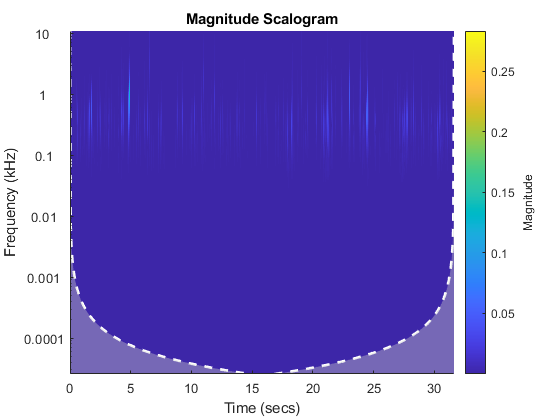

cwt(selected_ch,'morse',fs,'WaveletParameters',[3,10]); % Filtered data spectrogram different Morse paramters

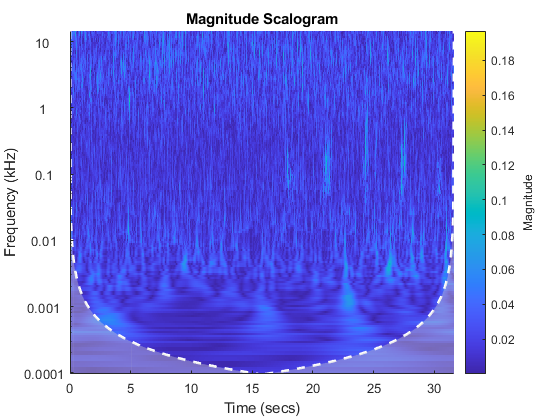

neural_ch1 = raw_data_norm(:,1);
cwt(neural_ch1,'morse',fs,'WaveletParameters',[100,150]); % Unfiltered Neural data spectrogram

toc

Elapsed time is 107.470924 seconds.


% colormap(gray(40));

% HHT

data = load('project_data.mat')

data = struct with fields:
              Kinematics: [948199×2 double]
    unfilteredNeuralData: [948199×6 single]


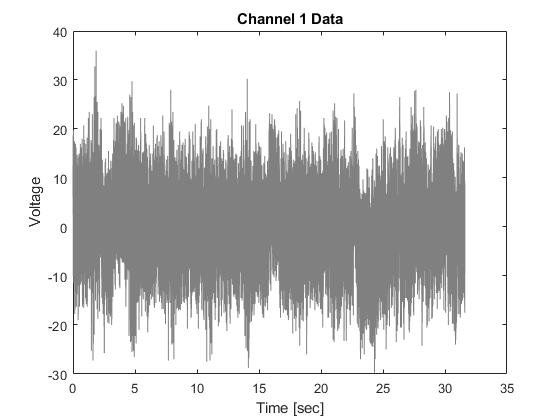

signal = data.unfilteredNeuralData(:,1);

fs = 30e3; % sampling frequency
t = (1:length(signal))'/fs;


figure;
plot(t,signal,'Color', [0.5 0.5 0.5]);
ylabel("Voltage")
xlabel("Time [sec]")
title("Channel 1 Data")

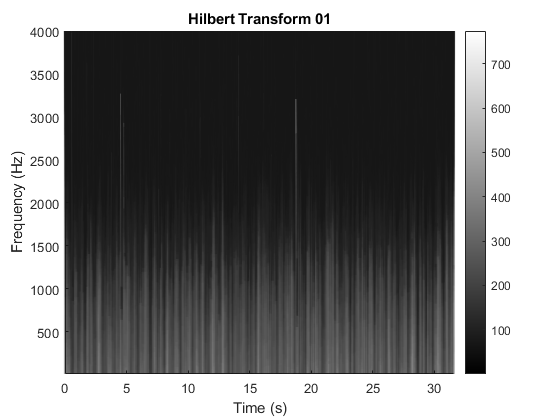

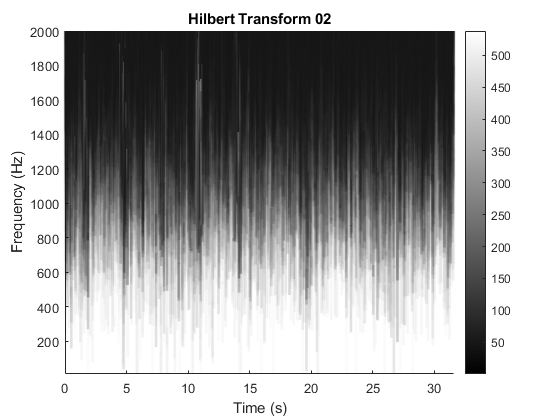

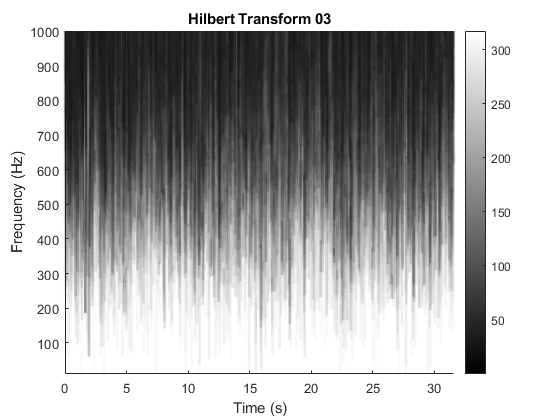

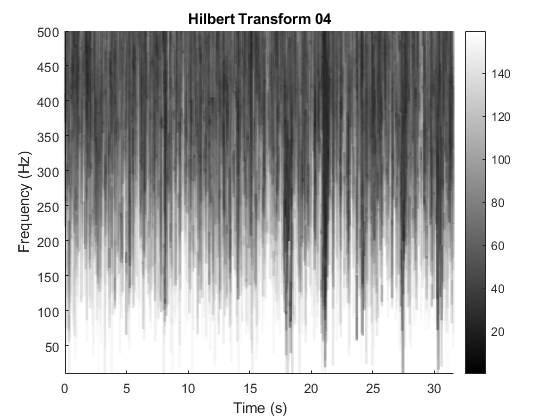

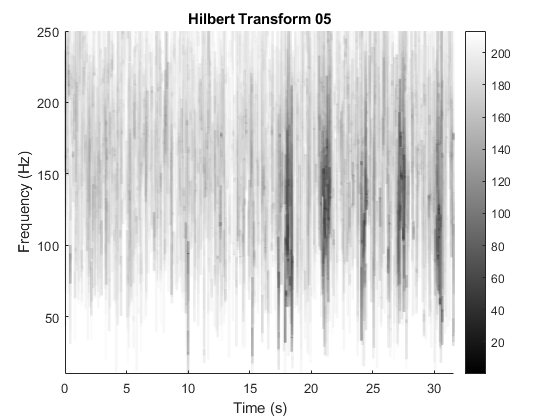



n_imf = 5;
imf = emd(signal,'MaxNumIMF',n_imf,'Display',0);


% Plot HHT of each IMF
for i = [1,2,3,4,5]
figure;
hht(imf(:,i),fs,FrequencyLimits=[10 8000/(2^i)])
colormap('gray');
title(sprintf("Hilbert Transform %02d", i))
end

## Helper Functions

function denoised_signal = swt_denoise_signal(neural_signal, decomp_levels, quiescent_idxs, clear_approx, show_fig)
% reformat for swt
x = double(neural_signal);
% extend signal accordingly
ROW_LEN = ceil(length(x)/2^decomp_levels) * 2^decomp_levels-length(x);
x = wextend('2D', 'ppd', x, [ROW_LEN,0],'d');
% DECOMPOSE
[swa, swd] = swt(x, decomp_levels, 'haar');
% DENOISE
denoised_swd = zeros(size(swd));
for j = 1:decomp_levels
    noise_intensity = median(abs(swd(j, quiescent_idxs)))/0.6475;
    N = length(swd(j, :));

    % Han et al. Threshold
    thresh_han = noise_intensity * sqrt(2*log(N));
    if j == decomp_levels
        thresh_han = thresh_han / sqrt(j);
    elseif j > 1
        thresh_han = thresh_han / log(j+1);
    end

    % hard thresholding
    denoised_swd(j, :) = wthresh(swd(j, :), 'h', thresh_han);
end

% RECONSTRUCT
if clear_approx
    mzero = zeros(size(swa));
    denoised_signal = iswt(mzero, denoised_swd, 'haar');
else
    denoised_signal = iswt(swa, denoised_swd, 'haar');
end

if show_fig
    figure()
    subplot(2,1,1), plot(x);
    title('Original signal')
    subplot(2,1,2), plot(denoised_signal);
    title('Denoised signal')
end
end